# Fisherfaces

First, load the training data (which contains a 256x256x106 matrix with 106 images that are each 256x256 pixels). Rename the imported varaibles, since the train data, which will be imported later, has the same variable names.

load classdata_test.mat
grayfaces_train = grayfaces;
y_train = y;

Make matrix A, which is the image data, but reshaped so that each image is a 65536 element column vector. 

A1 = reshape(grayfaces, 65536, 318);
size(A1)

ans =        65536         318


clear grayfaces

Normalize matrix A by making a matrix by repeating a column vector that contains the sum of each row, and subtracting the resulting matrix from A. 

A = A1 - repmat((sum(A1,2)./318),1,318);
clear A1

## Divide data into classes

Multiply each column by 6

normalized_classes = zeros(65536,53);
within_class_avgs = zeros(65536,53);
for class_num = 53
    six_faces = A(:,(class_num*6-6):class_num*6-1);
    within_class_avg = sum(six_faces,2)./6;
    within_class_avgs(:,class_num) = within_class_avg;
    normalized_classes(:,class_num) = within_class_avg*6;
end

Sb = 53x53 matrix

Sb = transpose(normalized_classes)*normalized_classes;

Sw = 6x6 matrix

Sw = zeros(6,6);
for class_num = 53
    six_faces = A(:,(class_num*6-6):class_num*6-1);
    six_repeated = repmat(within_class_avgs(:,class_num),1,6); %if error change 1 to 2
    Swn = transpose(six_faces-six_repeated)*(six_faces-six_repeated);
    Sw = Sw + Swn;
end

Sw = Sw./53

Sw = 	1.0e+06 *

    2.0761   -0.3766   -0.5060   -0.1216   -0.5325   -0.5394
   -0.3766    0.3094    0.0506    0.1156   -0.0282   -0.0709
   -0.5060    0.0506    0.3008   -0.2183    0.1762    0.1966
   -0.1216    0.1156   -0.2183    0.8312   -0.2897   -0.3173
   -0.5325   -0.0282    0.1762   -0.2897    0.3460    0.3281
   -0.5394   -0.0709    0.1966   -0.3173    0.3281    0.4029


[V,D,W] = eig(Sb,Sw)

Error using eig
For generalized eigenproblem, input matrices must be the same size.

Find U with equation ui = A*vi

 U1 (65536x106) 

U1 = (A*V);
clear U
clear S
clear V

Determine which eigenvectors from U are most important (which have the largest eigenvalues, but the first few have to do with lighting, so dispose of those), and throw out all the unnecessary eigenvectors and values. 

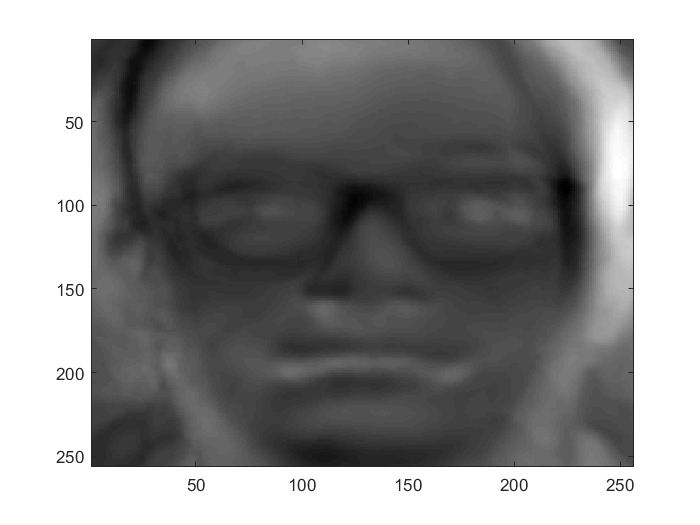

U20 = U1(:,4:18); % extract 20 entries
imagesc(reshape(U20(:,1), 256, 256)); colormap('gray') %display an eigenface

Then find out how much of each eigenvector is used to represent each face (find weights).

Weights = Transpose(U)*Image

Wtrain = transpose(U20)*A;

## When given a new face, find the weights and compare those to all existing weights 

Load test version of grayfaces and y, and assign to their own variables

load classdata_train.mat
grayfaces_test = grayfaces;
y_test = y;

Reshape and normalize in the same way as with the training data

A1 = reshape(grayfaces, 65536, 106);
size(A1)

ans =        65536         106


Atest = A1 - repmat((sum(A1,2)./106),1,106);
clear A1
Wtest = transpose(U20)*Atest;

Select random image from testing set, run random image through a for loop that compares every weight vector in the train matrix with the selected test image's weights, finds the minimum difference between the test image and the train image (the closest image between the test and train images). 

Display images, check if asociated names are the same, and return true if so, and false if not

n = randi([1 106],1,1) %emma is 36

n = 21

Wn = Wtest(:,n);
WL = zeros(1,318);
for i = 1:318
   WL(i) = WL(i)+ sum(abs(Wtrain(:,i)-Wn));
end
[M,I] = min(WL)

M = 1.9080e+08

I = 61

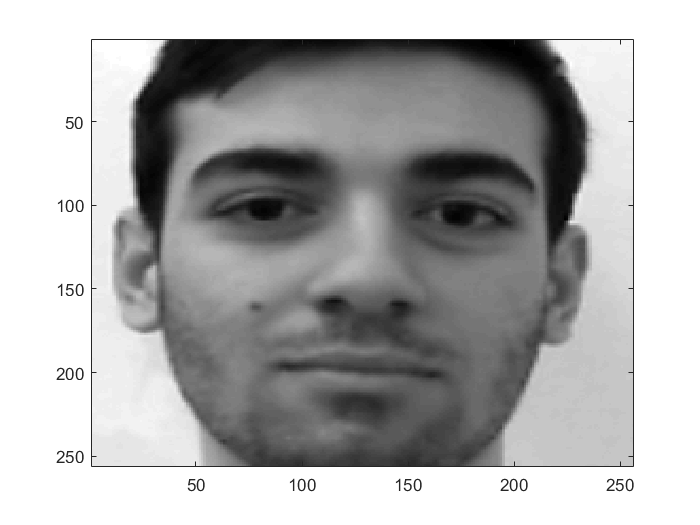


imagesc(grayfaces_train(:,:,I)); colormap('gray')

y_train.name(I)

ans = 1×1 cell array
    {'david_tarazi'}


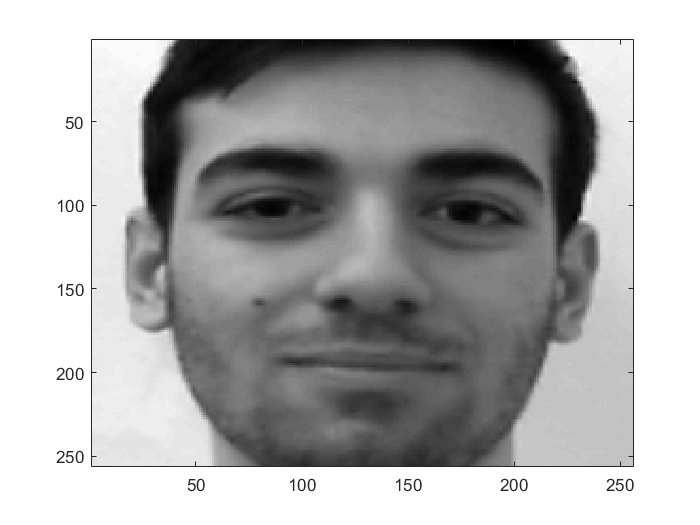

imagesc(grayfaces_test(:,:,n)); colormap('gray')

y_test.name(n)

ans = 1×1 cell array
    {'david_tarazi'}



if strcmp(y_train.name(I), y_test.name(n))
    disp("true")
else
    disp("false")
end

true


## Run for all faces in test set and determine accuracy

Change number of eigenvectors and run again

U20 = U1(:,3:28); %change which and how many eigenvectors are used
Wtrain = transpose(U20)*A;
Wtest = transpose(U20)*Atest;

num_true = 0;
num_false = 0;
tagged_false = 0;
tagged_false_list = [];
false_list = [];
for n = 1:106
    Wn = Wtest(:,n);
    WL = zeros(1,318);
    for i = 1:318
       WL(i) = WL(i) + sum(abs(Wtrain(:,i)-Wn));
    end
    [M,I] = min(WL);
    if sum(abs(Wtrain(:,i)-Wn)) > 350000000
%       disp("Probably incorrect")
       tagged_false = tagged_false + 1;
       tagged_false_list = [tagged_false_list,n];
    end
    if strcmp(y_train.name(I), y_test.name(n))
        num_true = num_true+1;
        %disp(sum(WL))
    else
        num_false = num_false+1;
        in = [I,n];
        false_list = [false_list, n];
    end
end

disp("Number correct: "+ num_true)

Number correct: 105


disp("Number incorrect: "+ num_false)

Number incorrect: 1


disp("Percentage correct: "+num_true/(num_false+num_true)*100)

Percentage correct: 99.0566


%disp("Tagged False: "+tagged_false)
%false_list = sort(false_list)

## Data:

With 20 Eigenvectors: (experimenting with how many to cut off in the beginning. Ideal seems to be starting at 4)

3:22 -> 87.7% 

4:23 -> 92.5%

5:24 -> 90.9%

It takes 5 eigenvectors to get the accuracy above 50% when starting at the 4th eigenvector

All of this data was taken starting at the 4th Eigenvector (one with 4th highest asociated eigenvalue):

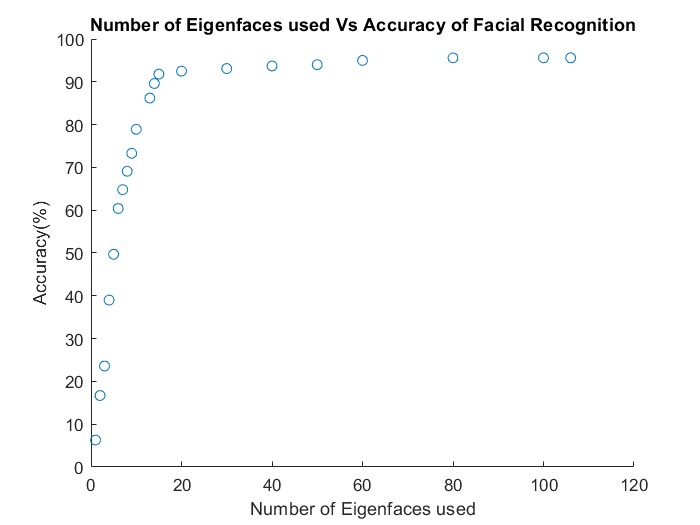

D = [1 6.3
2 16.7
3 23.6
4 39.0
5 49.7
6 60.4
7 64.8
8 69.1
9 73.3
10 78.9
13 86.2
14 89.6 
15 91.8
20 92.5
30 93.1
40 93.7
50 94.0
60 95.0
80 95.6
100 95.6
106 95.6];
scatter(D(:,1),D(:,2))
title("Number of Eigenfaces used Vs Accuracy of Facial Recognition")
xlabel("Number of Eigenfaces used")
ylabel("Accuracy(%)")

It seems like the ideal number of eigenvectors to use in order to have get the most accuracy without using too much processing power is 15.